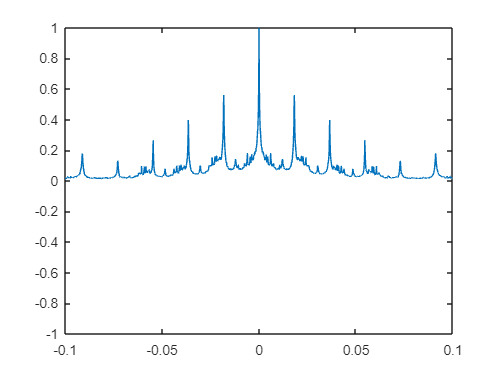

clear
clc

fs = 8000;
load("329.63Hz.mat");
N = length(nFP1);
[autocor,lags] = xcorr(nFP1,fs,'coeff');
plot(lags/fs,autocor)
axis([-0.1 0.1 -1 1])

[pklg,lclg] = findpeaks(autocor,'MinPeakheight',0.3*max(autocor));
f=mean(diff(lclg))*fs/2/N

f = 329.1995